# Test the Model

## Read in optimised hyperparameters

LSTMCNN

optVars = load("HyperParameterSearch\OptVars\LSTMCNNoptVars.mat").optVars;
miniBatchSize = optVars.miniBatchSize;
learningrate = optVars.learningrate;
numLSTMBlocks = optVars.numLSTMBlocks;
numHiddenUnits = optVars.numHiddenUnits;
numCNNBlocks = optVars.numCNNBlocks;
filterSize = optVars.filterSize;
numFilters = optVars.numFilters;

LSTM

optVars = load("HyperParameterSearch\OptVars\LSTMoptVars.mat").optVars;


## Test the model several times

rng(1);
numTesting = 10;
Maxepochs = 30;

LSTMCNN

accuracy = {};
confusionmats = {};
for i = 1:numTesting
    % load data set
    XTrain = load(['DataSet\Test\Train\XTestTrain' num2str(i) '.mat']).XTestTrain;
    YTrain = load(['DataSet\Test\Train\YTestTrain' num2str(i) '.mat']).YTestTrain;
    XTest = load(['DataSet\Test\Test\XTestTest' num2str(i) '.mat']).XTestTest;
    YTest = load(['DataSet\Test\Test\YTestTest' num2str(i) '.mat']).YTestTest;    
    % model
    numResponse = numel(categories(YTest{1}));
    numFeatures = size(XTrain{1},1);
    layers = constructLSTMCNN(numFeatures,numLSTMBlocks,numHiddenUnits, ...
        numCNNBlocks,filterSize,numFilters,numResponse,false); 
    % train
    options = trainingOptions('adam', ...
        'MaxEpochs',Maxepochs, ...
        'MiniBatchSize',miniBatchSize, ...
        'InitialLearnRate',learningrate, ...
        'LearnRateDropPeriod',10, ...
        'LearnRateDropFactor',0.75, ...
        'LearnRateSchedule','piecewise', ...
        'Plots','none',...
        'GradientThreshold',1, ...
        'shuffle','every-epoch',...
        'Verbose',0,...
        'DispatchInBackground',true);
    net = trainNetwork(XTrain,YTrain,layers,options);
    % evaluate
    YPred = classify(net, XTest, "MiniBatchSize",miniBatchSize);
    valError = 0;
    for k = 1:length(YPred)
    valError = valError + mean(YPred{k} == YTest{k});
    end
    accuracy{end+1} = valError/length(YPred);
    TY = [];
    Y = [];
    YTest = YTest.';
    for k = 1:numel(YTest)
        TY = [TY;YTest{k}];
        Y = [Y;YPred{k}];
    end
    confusionMat = confusionmat(TY(:),Y(:));
    confusionmats{end+1} = confusionMat;
end

result = table(accuracy, confusionmats);
save('Test\Results\LSTMCNNresult.mat','result','-mat');

## Standard deviation of accuracy

accuracyList = [];
accuracy = load('Test\Results\LSTMCNNresult.mat').result.accuracy;
for i = 1:numTesting
    accuracyList = [accuracyList, accuracy{i}];
end
accuracyMean = mean(accuracyList)

accuracyMean = 0.9321

accuracyStd = std(accuracyList)

accuracyStd = 0.0026

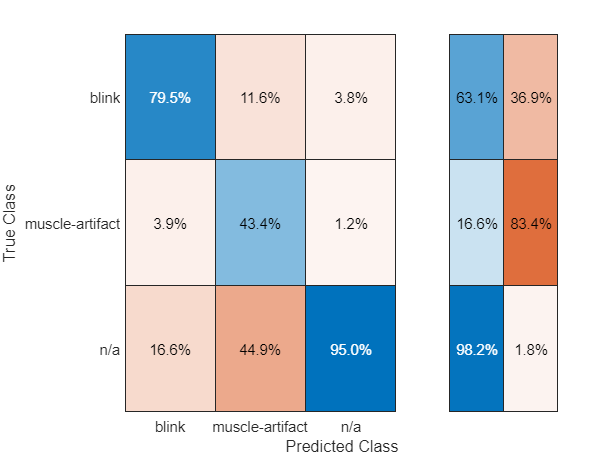

figure;
confusionchart(load('Test\Results\LSTMCNNresult.mat').result.confusionmats{1},{'blink' 'n/a' 'muscle-artifact'},'Normalization','column-normalized','RowSummary','row-normalized');